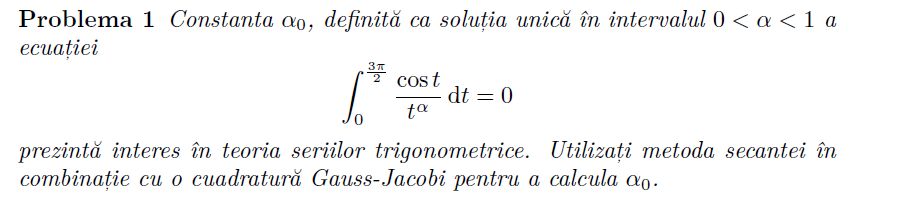

%{
clear
syms x
f = @(x) cos(x) - x;
x0 = 0.5;
x1 = pi / 4;
fprintf("Metoda secanta:")
[rad, iter]= secanta(f, x0, x1)
[g_nodes, g_coeff] = Jacobi(n, a, b);
jacobi_value = vquad(g_nodes, g_coeff, g);
%}
n=15; er=0.5e-14;
fa(0.25,er)

Unrecognized function or variable 'Gauss_Jacobi_ab'.

Error in test>fa (line 18)
[g_nodes,g_coeffs]=Gauss_Jacobi_ab(n, 0, -a, 0, 3*pi/2);

function y=fa(a,eps0)
    f=@(t) cos(t);
    n=10; valfv=0;
    nmax=50; n=5;
    [g_nodes,g_coeffs]=Gauss_Jacobi_ab(n, 0, -a, 0, 3*pi/2);
    valf=vquad(g_nodes,g_coeffs,f);
    for k=1:nmax
        valfv=valf; n=n+1;
        [g_nodes,g_coeffs]=Gauss_Jacobi_ab(n, 0, -a, 0, 3*pi/2);
        valf=vquad(g_nodes,g_coeffs,f);
        if abs(valf-valfv)<=eps0
            y=valf;
            nef=n;
            return
        end %if
    end
    nef=nmax;
end